Given data points we will constuct a P3 and compare it with the sin function from 0 to pi/2.

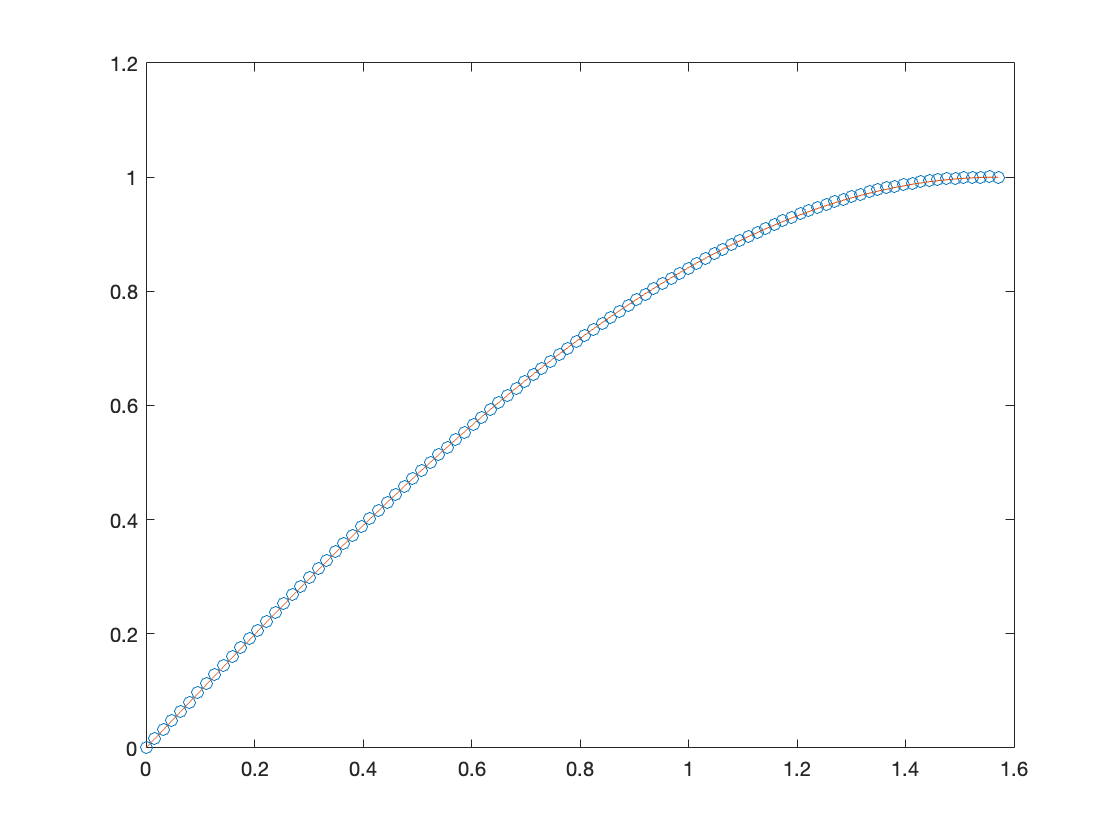

y0 = [0,1/2,sqrt(3)/2,1];
x0 = linspace(0,pi/2,4);
x1 = linspace(0,pi/2);
yA = sin(x1);
p3 = polyfit(x0,y0,3);
y1 = polyval(p3,x1);
plot(x1,y1,'o')
hold on 
plot(x1,yA)
hold off

Above is the approximation of the data points using a 3rd degree polynomial. Lets apply some properties so we can use it for any x.

xa = 10*randn(1)

xa = -15.6506

x = xa;
si = 1;
while abs(x) > 2*pi 
if x > 2*pi    
    x = x - 2*pi
end
if x < -2*pi
    x = x + 2*pi 
end
if x == abs(2*pi) || x == 0
    x = 0;
    break
end
end

x = -9.3674

x = -3.0842

x

x = -3.0842

if x < 0 && x > -pi/2
    si = -1
end
if abs(x) < 2*pi
    if x < 0
        x = x + 2*pi
    end
    if x >= 3*pi/2
        x = x - 2*pi;
        x = abs(x);
        si = -1
    end    
    if x >= pi && x < 3*pi/2
        x = x - pi
        si = -1
    end
    if x >= pi/2 && x < pi 
        xt = x - pi/2;
        x = pi/2 - xt
    end    
end

x = 3.1990

x = 0.0574

si = -1


% x is now in abs value range so we must check if x is negative we make the
% corresponding y negative as well.
x

x = 0.0574

if x < 0
    yg = si*polyval(p3,-x)
else  
    yg = si*polyval(p3,x)
end

yg = -0.0583

abs(sin(xa)-yg)

ans = 9.6692e-04

Above I map every real x to the subset [0,pi/2] and produce a good result using the properties to correctly map every x to our interval.

Chebyshev Polynomial 

Below we will plot the chebyshev polynomial. 

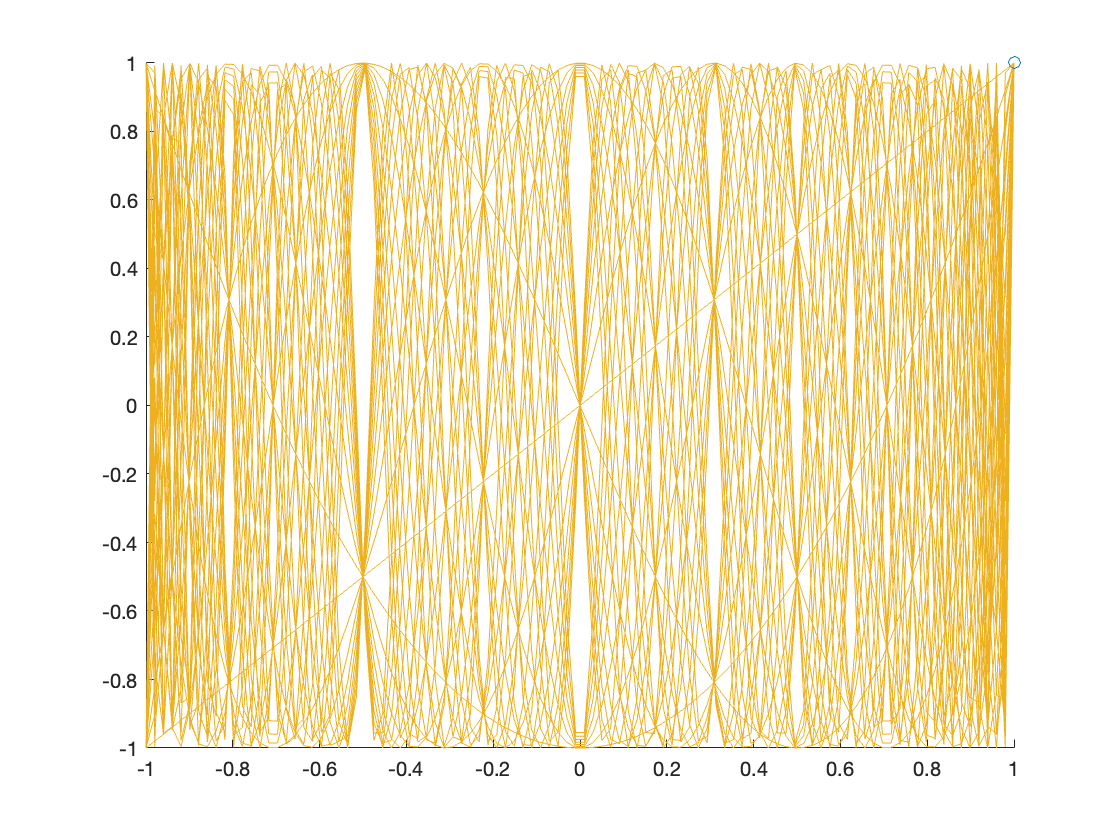

x = linspace(-1,1);
for i = 1:30
    cheb = cos(i*acos(x));
    comet(x,cheb)% slowly plots it to see what happens with each step
    hold on;
end

From the plot we see that the chebyshev polynomial looks like a x to the ith degree function from -1 to 1. The pdf  